# Panel models with cross sections

Tutorial file for testing panel models

## Housekeeping

clear
close all

import cross.*

## Convenience functions

percentiles = [10, 50, 90];

prctileFunc = @(x) prctile(x, percentiles, 2);

extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];

medianFunc = @(x) median(x, 2);

flatFunc = @(x) x(:, :);

defaultColors = get(0, "defaultAxesColorOrder");

## Number of Samples

numPresampled = 100;

## Prepare meta information for the models

Note that the meta information is common to all cross-section panel BVAR models, regardless of the specific estimator used.

The properties are as follows:

**endogenousConcepts **–  a list of endogenous variables, listed without the country suffix. Plays the same role as **endogenousNames** in plain BVARs

**units **– a list of countries/units that share the same endogenous variables


estimStart = datex("1972-Q1");
estimEnd = datex("2014-Q4");
estimSpan = datex.span(estimStart, estimEnd);

meta = Meta( ...
    endogenousConcepts=["YER", "HICSA", "STN"], ...
    units=["US", "EA", "UK"], ...
    exogenous=["Oil"], ...
    order=4, ...
    intercept=true, ...
    estimationSpan=estimSpan, ...
    identificationHorizon=20, ...
    shockConcepts=["DEM", "SUP", "POL"] ...
);



## Specifying and loading input data


inputTbl = tablex.fromFile("data/panel_data.csv");
dataH = DataHolder(meta, inputTbl);

## Reduced form models

There are some common properties for the cross section panel BVARs. Which are

**Alpha0 (1000)** – The shape of the Inverse Gamma distribution of residual variances

**Delta0 (1)** – The scale of the Inverse Gamma distribution of residual variances

#### Static Cross Panel

estimatorR1 = estimator.StaticCrossPanel(meta);

#### Dynamic Cross Panel

**A0 (1000)** – The shape of the Inverse Gamma distribution of factor variances

**B0 (1)** – The scale of the Inverse Gamma distribution of factor variances

**Rho (0.75)** – The AR coefficient in the prior for factor coefficients.

**Gamma (0.85)** – The AR coefficient for latent innovation series

% estimatorR1 = estimator.DynamicCrossPanel(meta);

### Creating the reduced form model


modelR1 = ReducedForm( ...
    meta=meta, ...
    dataHolder=dataH, ...
    estimator=estimatorR1 ...
);

## Estimation/sampling of the reduced form model 


modelR1.initialize();
info0 = modelR1.presample(numPresampled);


 Presampling from posterior (StaticCrossPanel) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelR1.Presampled{1}.beta

ans =     0.2170
    0.1593
    0.1593
    0.1666
    0.1090
    0.1090
    0.1666
    0.1090
    0.1090
    0.0033
   -0.0544
   -0.0544
   -0.0471
   -0.1047
   -0.1047


## Running Unconditional forecast 

### Settig up the forecast range and run the forecast

fcastStart = datex.shift(modelR1.Meta.EstimationEnd, -10); %The forecast starts 10 periods prior to the end of the estimation span.
fcastEnd = datex.shift(modelR1.Meta.EstimationEnd, 0); %The forecast ends at the end of the estimation window.
fcastSpan = datex.span(fcastStart, fcastEnd);

fcastStart, fcastEnd

fcastStart = datetime
   2012-Q2


fcastEnd = datetime
   2014-Q4



fcastTbx = modelR1.forecast(fcastSpan);
fcastPrctileTbx = tablex.apply(fcastTbx, prctileFunc);
fcastPrctileTbx = tablex.flatten(fcastPrctileTbx); %keeping only the pctiles set at the beginning of the file (10, 50, 90)


### Visualize the unconditional forecast

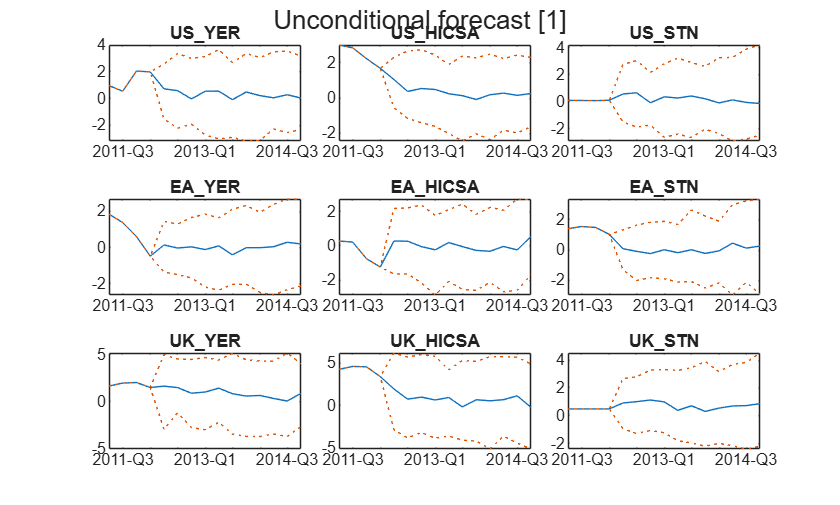

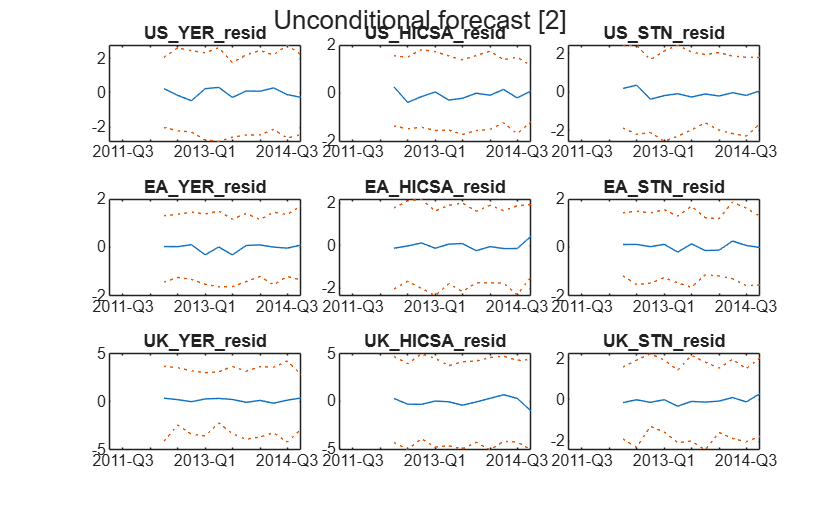

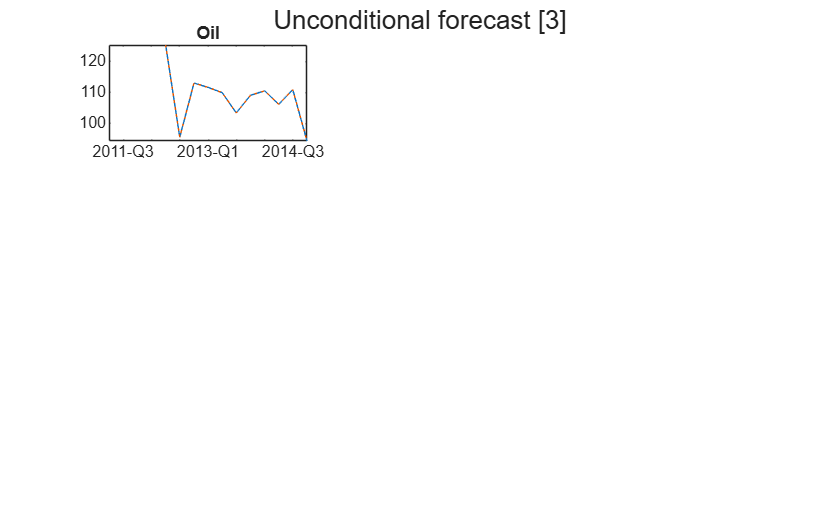

ans = 1×3 cell array
    {1×1 Figure}    {1×1 Figure}    {1×1 Figure}



chartpack.forecastPercentiles( ...
    fcastPrctileTbx, modelR1, FigureTitle ="Unconditional forecast")

## Identification

### Cholesky

#### Setting up the identifier

identChol = identifier.Cholesky(order=[]);

modelS1 = Structural(reducedForm=modelR1, identifier=identChol);
modelS1.initialize();

info1 = modelS1.presample(numPresampled);


 Presampling from posterior (StaticCrossPanel) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelS1.Presampled{1}

ans = struct with fields:
                  beta: [342×1 double]
                 sigma: [81×1 double]
    IdentificationDraw: [1×1 struct]
                     D: [9×9 double]


#### Checking transition matrices

modelS1.Presampled{1}.IdentificationDraw

ans = struct with fields:
        A: {20×1 cell}
        C: {20×1 cell}
    Sigma: [9×9 double]


modelS1.Presampled{1}.IdentificationDraw.A{1,1}

ans =     0.2192    0.1576    0.1576    0.1656    0.1039    0.1039    0.1656    0.1039    0.1039
    0.1576    0.2249    0.1576    0.1039    0.1713    0.1039    0.1039    0.1713    0.1039
    0.1576    0.1576    0.2340    0.1039    0.1039    0.1804    0.1039    0.1039    0.1804
    0.1656    0.1039    0.1039    0.2208    0.1592    0.1592    0.1656    0.1039    0.1039
    0.1039    0.1713    0.1039    0.1592    0.2265    0.1592    0.1039    0.1713    0.1039
    0.1039    0.1039    0.1804    0.1592    0.1592    0.2356    0.1039    0.1039    0.1804
    0.1656    0.1039    0.1039    0.1656    0.1039    0.1039    0.2262    0.1645    0.1645
    0.1039    0.1713    0.1039    0.1039    0.1713    0.1039    0.1645    0.2319    0.1645
    0.1039    0.1039    0.1804    0.1039    0.1039    0.1804    0.1645    0.1645    0.2410
    0.0173   -0.0444   -0.0444   -0.0364   -0.0980   -0.0980   -0.0364   -0.0980   -0.0980
   -0.0444    0.0230   -0.0444   -0.0980   -0.0307   -0.0980   -0.0980   -0.0307   -

modelS1.Presampled{1}.IdentificationDraw.A{2,1}

ans =     0.2192    0.1576    0.1576    0.1656    0.1039    0.1039    0.1656    0.1039    0.1039
    0.1576    0.2249    0.1576    0.1039    0.1713    0.1039    0.1039    0.1713    0.1039
    0.1576    0.1576    0.2340    0.1039    0.1039    0.1804    0.1039    0.1039    0.1804
    0.1656    0.1039    0.1039    0.2208    0.1592    0.1592    0.1656    0.1039    0.1039
    0.1039    0.1713    0.1039    0.1592    0.2265    0.1592    0.1039    0.1713    0.1039
    0.1039    0.1039    0.1804    0.1592    0.1592    0.2356    0.1039    0.1039    0.1804
    0.1656    0.1039    0.1039    0.1656    0.1039    0.1039    0.2262    0.1645    0.1645
    0.1039    0.1713    0.1039    0.1039    0.1713    0.1039    0.1645    0.2319    0.1645
    0.1039    0.1039    0.1804    0.1039    0.1039    0.1804    0.1645    0.1645    0.2410
    0.0173   -0.0444   -0.0444   -0.0364   -0.0980   -0.0980   -0.0364   -0.0980   -0.0980
   -0.0444    0.0230   -0.0444   -0.0980   -0.0307   -0.0980   -0.0980   -0.0307   -

#### Checking scaling matrix

modelS1.Presampled{1}.D

ans =     1.5657   -0.3501   -0.4505    0.4162   -0.4433    0.2643    0.2045   -0.0154   -0.5717
         0    0.8981    0.3015   -0.3272   -0.1592    0.2318   -0.0403   -0.0709    0.1879
         0         0    1.3048    0.0374    0.0495    0.0981   -0.0470   -0.2869    0.0825
         0         0         0    0.9205   -0.8264    0.3198   -0.7710    0.9599    0.1484
         0         0         0         0    1.4588   -0.6267    1.0600   -1.2494    0.4290
         0         0         0         0         0    0.6866    0.0548   -0.4272    0.1531
         0         0         0         0         0         0    1.2635   -0.4632   -0.2014
         0         0         0         0         0         0         0    1.3346    0.0067
         0         0         0         0         0         0         0         0    0.9573


modelS1.Presampled{2}.D

ans =     1.4383   -0.3433   -0.3158    0.2556   -0.2633    0.2221    0.3381   -0.1623   -0.5889
         0    0.8234    0.1737   -0.2581   -0.0542    0.1665    0.0595   -0.1496    0.1262
         0         0    1.3140    0.0126    0.4804   -0.0791    0.3509   -0.6654    0.1297
         0         0         0    0.8302   -0.6028    0.2950   -0.3740    0.7474    0.0816
         0         0         0         0    1.4859   -0.5866    0.9993   -1.4663    0.4626
         0         0         0         0         0    0.6682    0.0858   -0.3721    0.1317
         0         0         0         0         0         0    1.3556   -0.5681   -0.1802
         0         0         0         0         0         0         0    1.3173   -0.1290
         0         0         0         0         0         0         0         0    0.9163


## Impulse responses (IRF)

### Cholesky

respTbl1 = modelS1.simulateResponses();


  (StaticCrossPanel) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



respTbl1 = tablex.apply(respTbl1, prctileFunc);
respTbl1 = tablex.flatten(respTbl1);

respTbl1

respTbl1 = 21×81 timetable
     Time                 US_YER___US_DEM                             US_YER___US_SUP                         US_YER___US_POL                        US_YER___EA_DEM                             US_YER___EA_SUP                         US_YER___EA_POL                        US_YER___UK_DEM                           US_YER___UK_SUP                        US_YER___UK_POL                        US_HICSA___US_DEM                       US_HICSA___US_SUP                   US_HICSA___US_POL                      US_HICSA___EA_DEM                          US_HICSA___EA_SUP                          US_HICSA___EA_POL                          US_HICSA___UK_DEM                          

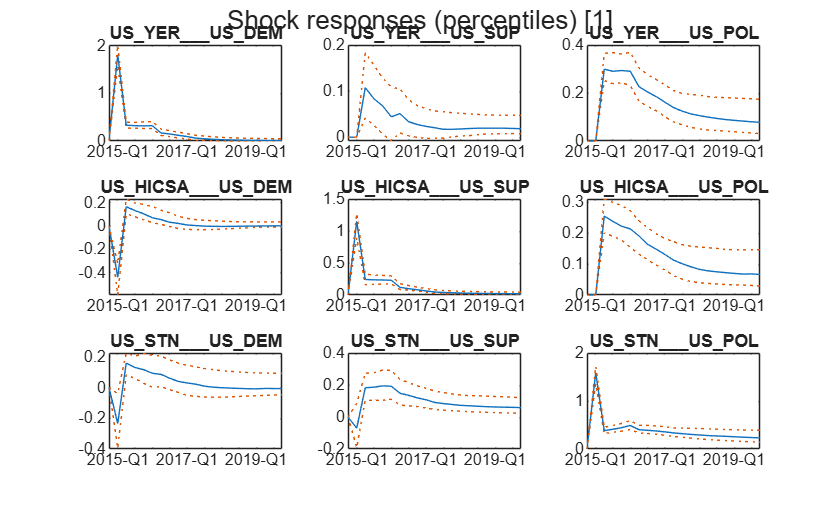

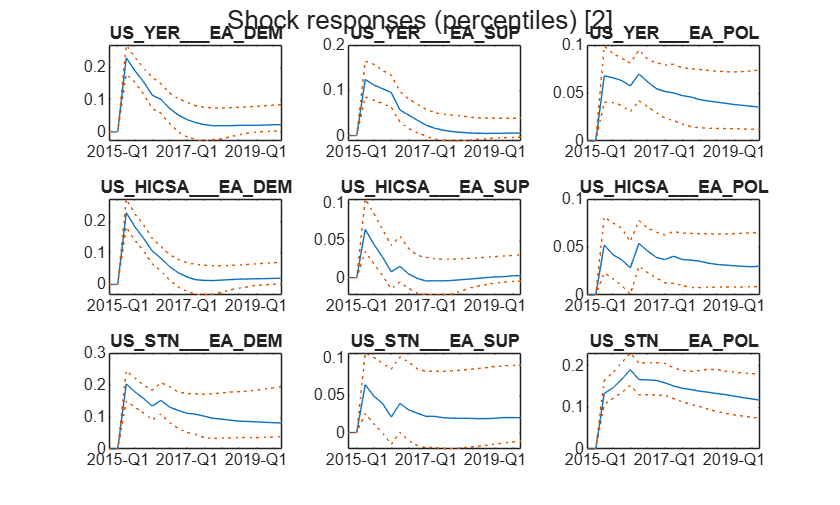

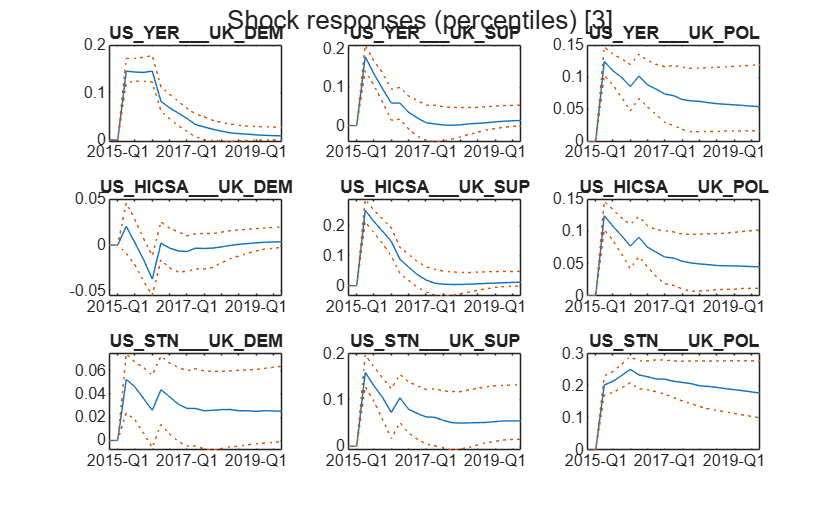

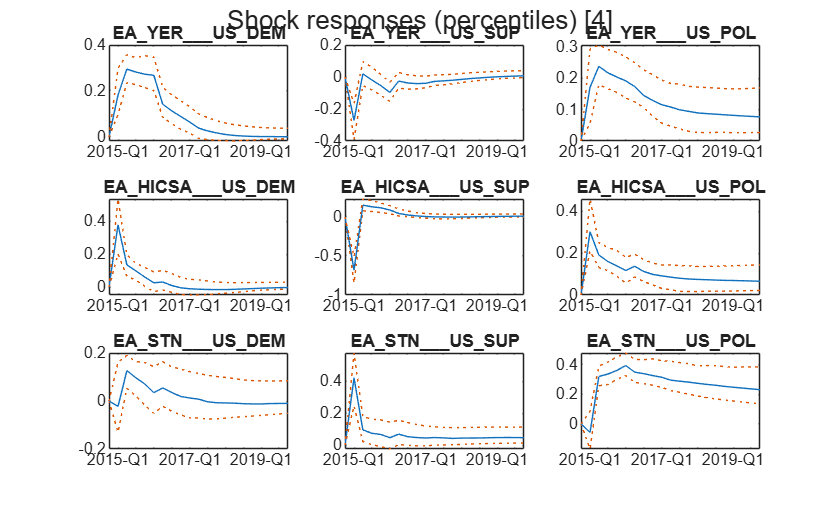

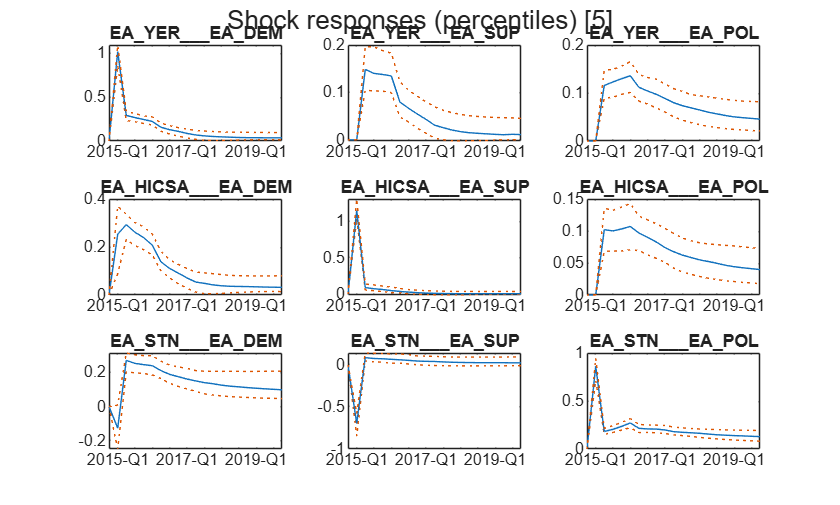

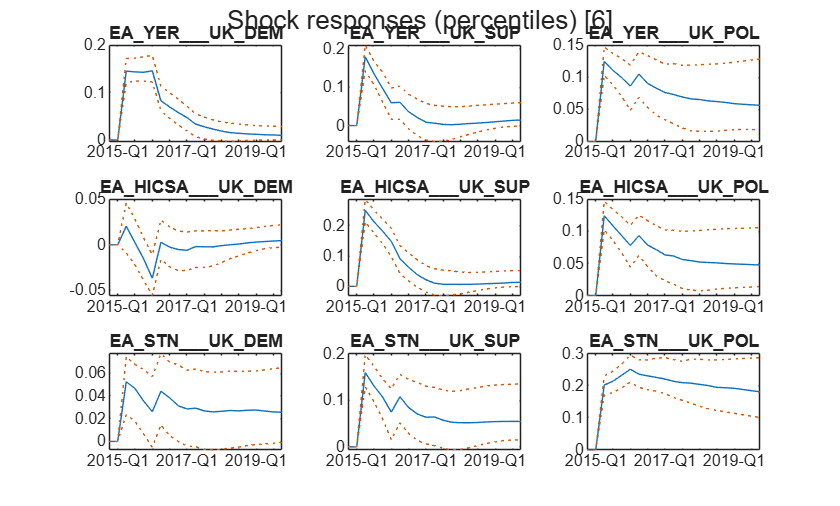

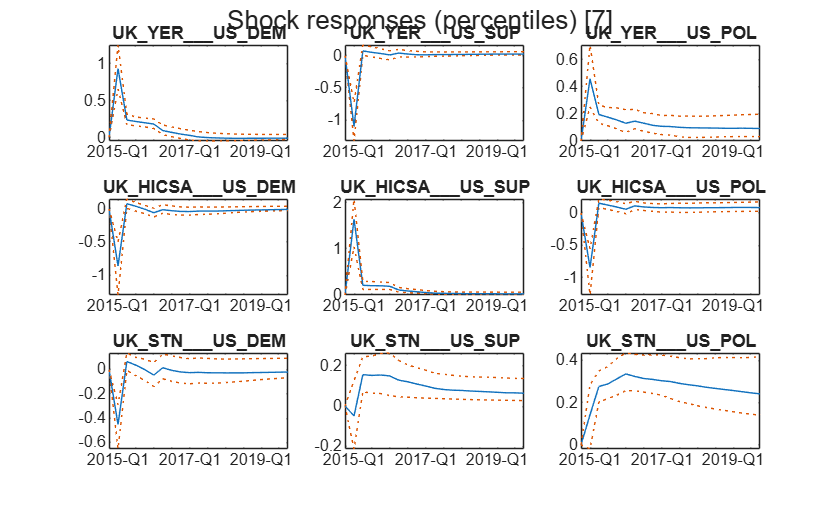

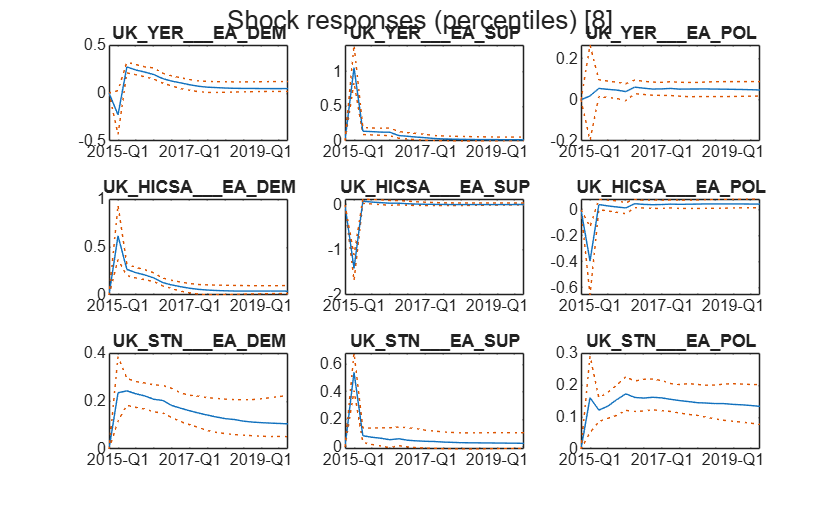

chartpack.responsePercentiles( ...
    respTbl1, modelS1 ...
    , "figureTitle", "Shock responses (percentiles)" ...
);

## **Historical shock decomposition**


histContTbx = modelS1.calculateContributions();

tablex.getHigherDims(histContTbx)

ans = 1×1 cell array
    {["US_DEM"    "US_SUP"    "US_POL"    "EA_DEM"    "EA_SUP"    "EA_POL"    "UK_DEM"    "UK_SUP"    "UK_POL"    "Exogenous"    "Initials"]}


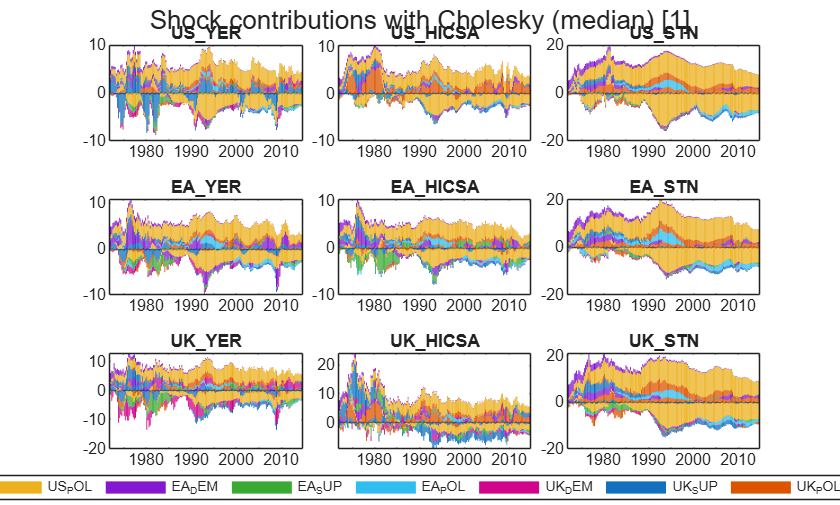


histContMedTbx = tablex.apply(histContTbx, medianFunc);

chartpack.contributionsMedian( ...
    histContMedTbx, modelS1 ...
    , "figureTitle", "Shock contributions with Cholesky (median)" ...
);

## **Unconditional forecast shock decomposition**


[uncFcastTbl1, uncFcastContribTbl1] = modelS1.forecast( ...
    fcastSpan, ...
    contributions=true ...
);

tablex.getHigherDims(uncFcastContribTbl1)

ans = 1×1 cell array
    {["US_DEM"    "US_SUP"    "US_POL"    "EA_DEM"    "EA_SUP"    "EA_POL"    "UK_DEM"    "UK_SUP"    "UK_POL"    "Exogenous"    "Initials"]}


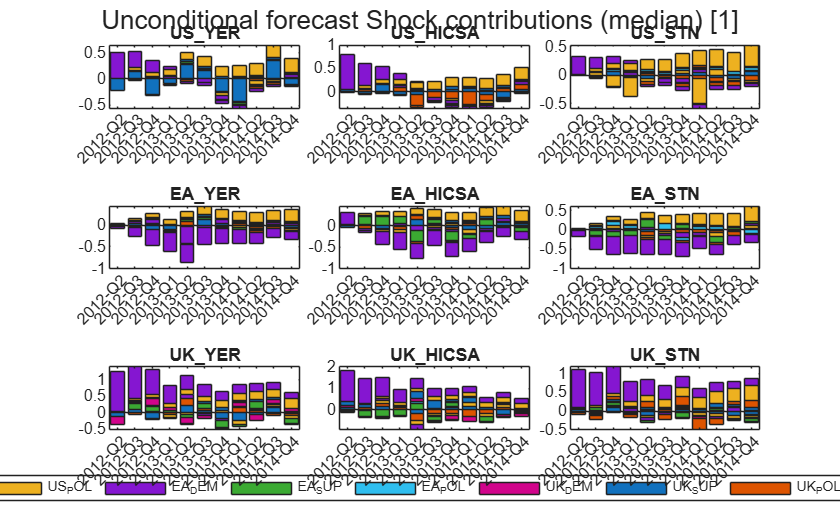


contMedTbx = tablex.apply(uncFcastContribTbl1, medianFunc);
contMedTbx = tablex.apply(contMedTbx, flatFunc);

chartpack.contributionsMedian( ...
    contMedTbx,modelS1 ...
    , "figureTitle", "Unconditional forecast Shock contributions (median)" ...
);

## **FEVD**


fevdTbx = modelS1.calculateFEVD();


  (StaticCrossPanel) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




tablex.getHigherDims(fevdTbx)

ans = 1×1 cell array
    {["US_DEM"    "US_SUP"    "US_POL"    "EA_DEM"    "EA_SUP"    "EA_POL"    "UK_DEM"    "UK_SUP"    "UK_POL"]}


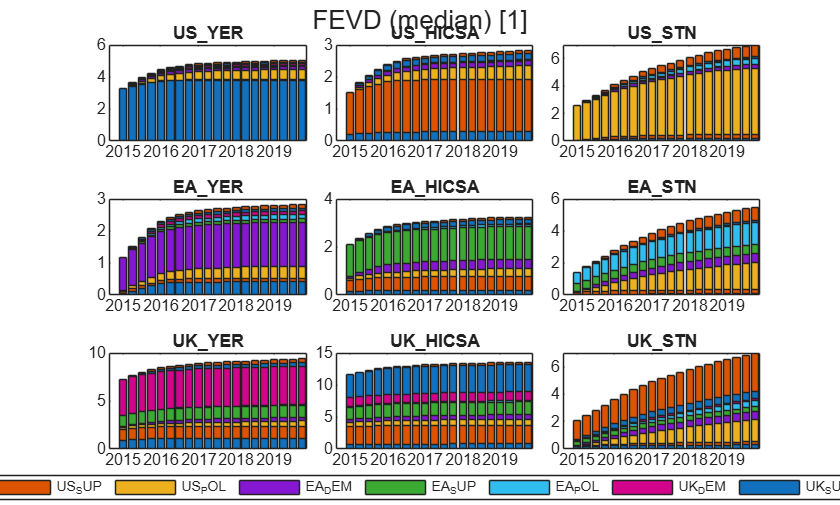


fevdMedTbx = tablex.apply(fevdTbx, medianFunc);
fevdMedTbx = tablex.apply(fevdMedTbx, flatFunc);

chartpack.contributionsMedian( ...
    fevdMedTbx,modelS1 ...
    , "figureTitle", "FEVD (median)" ...
);

## Conditional forecast

### Setting up the conditions and the forecast plan

condDataTbl = tablex.fromFile("data/condDataTblPanel.xlsx");
planTbl = tablex.readConditioningPlan("data/planTblPanel.xlsx");

### Setting up the forecast range 

cfcastStart = datex.shift(modelR1.Meta.EstimationEnd, 1); %The forecast starts after the estimation span.
cfcastEnd = datex.shift(modelR1.Meta.EstimationEnd, 12); 
cfcastSpan = datex.span(cfcastStart, cfcastEnd);

### Running conditional forecast with no simulation plan

[condFcastTbl1, condFcastContribTbl1] = modelS1.conditionalForecast( ...
    cfcastSpan, ...
    conditions=condDataTbl, ...
    plan=[], ...
    exogenousFrom = "conditions" ...
);


 Conditional forecast [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




condFcastPrctilesTbl1 = tablex.apply(condFcastTbl1, prctileFunc);

### Running conditional forecast with simulation plan

[condFcastTbl2, condFcastContribTbl2] = modelS1.conditionalForecast( ...
    cfcastSpan, ...
    conditions=condDataTbl, ...
    plan=planTbl, ...
    exogenousFrom = "conditions" ...
);


 Conditional forecast [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




condFcastPrctilesTbl2 = tablex.apply(condFcastTbl2, prctileFunc);

### Visualize the conditional forecast

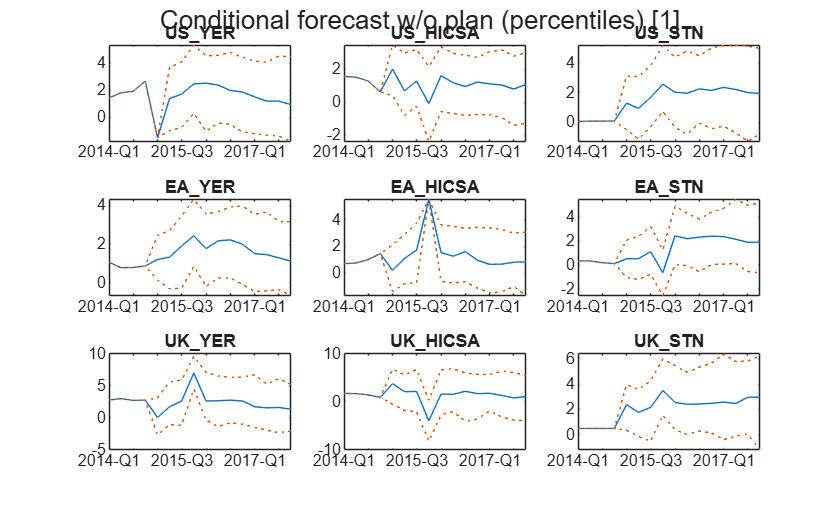

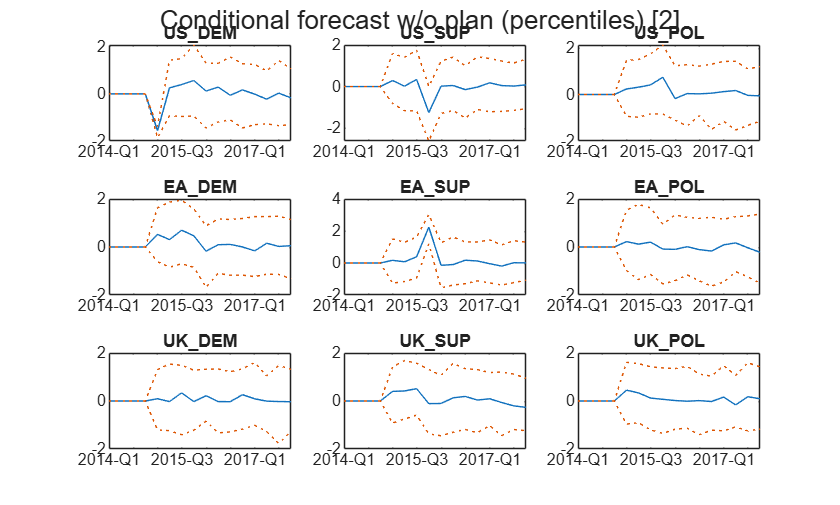

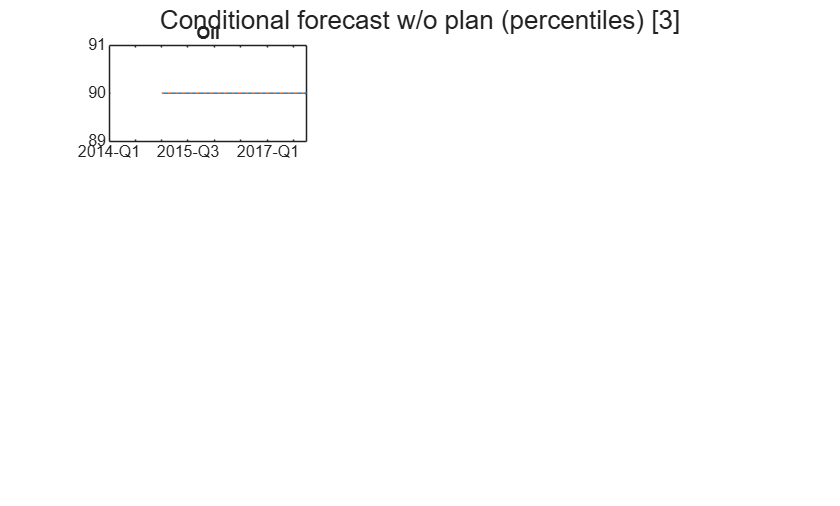

chartpack.conditionalForecastPercentiles( ...
    condFcastPrctilesTbl1,modelS1 ...
    , "figureTitle", "Conditional forecast w/o plan (percentiles)" ...
);

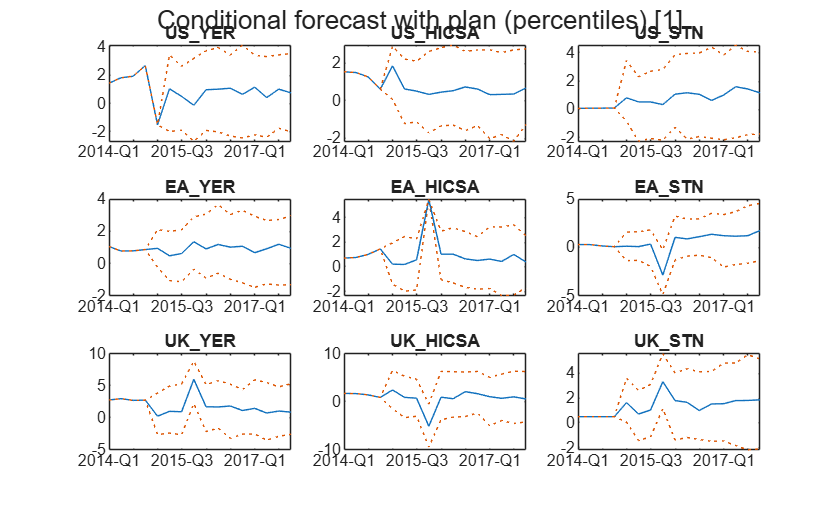

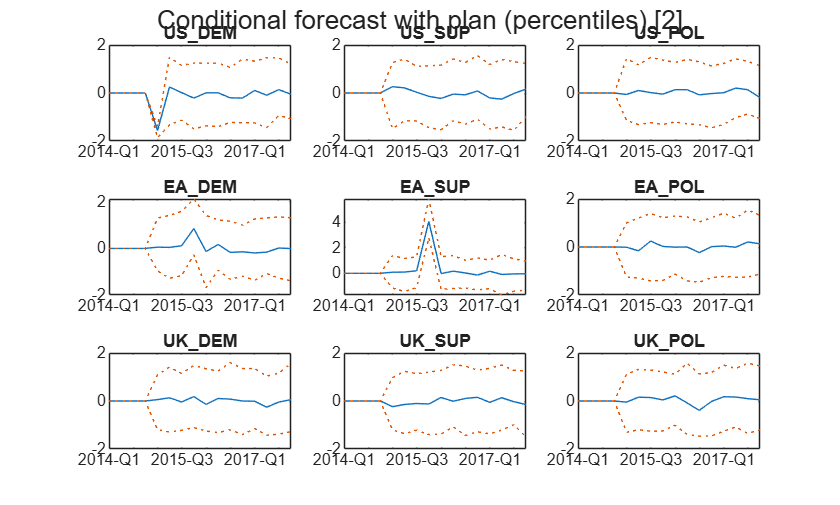

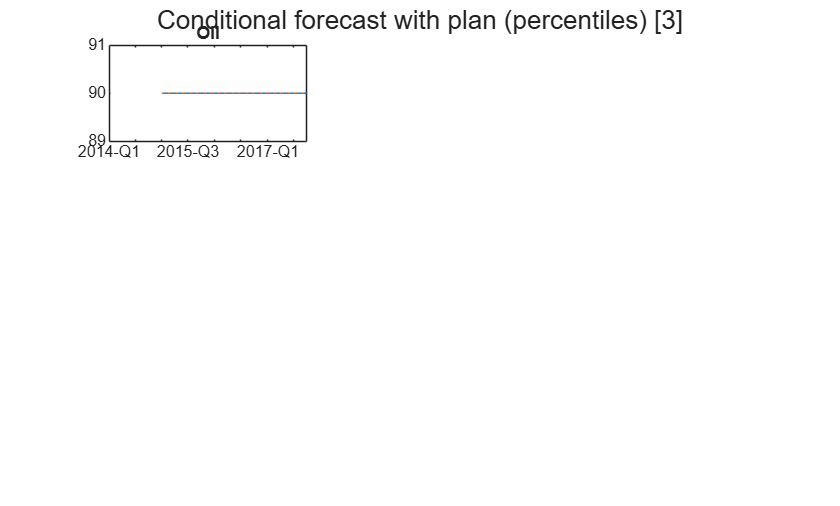


chartpack.conditionalForecastPercentiles( ...
    condFcastPrctilesTbl2,modelS1 ...
    , "figureTitle", "Conditional forecast with plan (percentiles)" ...
);